# Part 2: Reconeixement

Lectura del directori

close all
Idir = dir('./MotorcycleChase/img/*.jpg');

Dividim totes les imatges entre dos.

nf = size(Idir); % nombre total de fitxers imatges
for i = 1:nf
    filename = horzcat(Idir(i).folder,'/',Idir(i).name);
    I = imread(filename);
    imshow(I); % mostra el frame
end

Lectura del fitxer d'annotacions. Segueix el següent format:

[ID del frame, xmin, ymin, amplada, alçada, isLost] 

on cada ítem indica: frameID: 

- numero de frame. 

- xmin - Coordenada x superior esquerra del quadre delimitador. 

- ymin - Coordenada y superior esquerra del quadre delimitador. 

- amplada - Amplada del quadre. 

- altura - Alçada del quadre.

- isLost - Si és 1, l'objecte objectiu no és visible en absolut; altrament 0

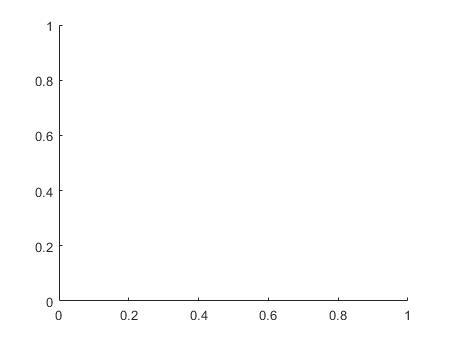

BB = importdata('./MotorcycleChase/groundtruth_rect.txt'); 

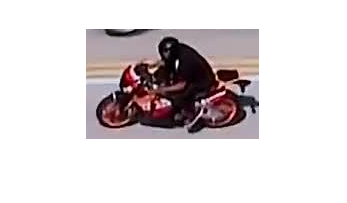

% 1,495,343,172,109,0

InitialObjectPosition = [BB(1,2) BB(1,3) BB(1,4) BB(1,5)];

Imatge de l'objecte a identificar.

filename = horzcat(Idir(1).folder,'/',Idir(1).name);
I = imread(filename);
hold on
imcrop(I, InitialObjectPosition);